# **Signals and Systems Lab Report**

**Q1.1: **Determine the period of $x(t)$ theoretically and check that it agrees with the period measured directly in the plot of $x$.

samplerate = 16e3; % Hz
t = (0:1/samplerate:2); % s
f1 = 32; % Hz
f2 = 40; % Hz
x = cos(2*pi*f1*t) + cos(2*pi*f2*t);
figure('Units', 'pixels', 'Position', [0, 0, 1000, 500]); 
plot(t,x)
%[xi, yi] = ginput;
period = mean(diff(xi))

Unrecognized function or variable 'xi'.

Theoretically, the fundamental period of the signal is the least common multiple (LCM) of the fundamental periods of each cosine.

When working with rational numbers (like the fundamental periods for each of the cosines, as they are the inverse of their frequencies), $\text{LCM} = \frac{\text{LCM of numerators } (=1)}{\text{GCD of denominators}}$.

theoretical_period = 1/gcd(f1, f2)

The period we measured, as the mean of the subsequent differences between periodic locations in the signal, agrees with the theoretical period we calculated above.

**Q1.2:** As discussed above, this "continuous-time" signal `x` in Matlab is actually a discrete-time signal. Determine its theoretical period in samples and check against the direct measurement taken from `plot(x)`.

The theoretical period in samples corresponds to the smallest integer that is a multiple of the period, which is obtained by multiplying the theoretical_period by (GCD) of the frequencies f1 and f2. (Acho que não)

theoretical_period_in_samples = theoretical_period*gcd(f1,f2)

Acho que é assim:

period_in_samples = theoretical_period*samplerate

Direct measurement:

plot(x);
[xx, yy] = ginput;
period2 = diff(xx)

If you now downsample it by a factor of 3, what will be the period of `y`, in samples?

y = downsample(x,3);
period_in_samples_y = theoretical_period*samplerate/3

Why does this only seemingly disagree with direct measurement from `plot(y)`?

plot(y);
[xxx,yyy] = ginput;
measured_period_samples_y = diff(xxx)

Teoricamente diferem por causa do domínio, o medido terá que ser um inteiro

**Q1.3:** Determine the frequencies of C4, E4, F#4, G4, B4. 

A4 = 440; % Hz
ratio = 2^(1/12);

% TODO: I should change this code into a reusable function that takes in a
% parameter which is like distance_from_A4...

C4 = A4 * ratio^(-9);
E4 = A4 * ratio^(-5);
Fs4 = A4 * ratio^(-3);
G4 = A4 * ratio^(-2);
B4 = A4 * ratio^(2);
F4 = A4*ratio^(-4) 

F4 = 349.2282

Use the `seqsin` function to generate a sequence of sinusoids and silence gaps. Create x as the following sequence and listen to the resulting signal:


$$\text{R(0.7), E4(0.25), E4(0.25), F4(0.25), F\#4(0.5), A4(0.25),} \\

\text{F\#4(0.25), A4(0.25), F\#4(0.25), F\#4(0.25), F4(0.25),} \\

\text{E4(0.25), B4(0.25), E4(0.25), E4(0.5), R(0.7)}$$


x = seqsin(samplerate, 0, 0.7, E4, 0.25, E4, 0.25, F4, 0.25, Fs4, 0.5, A4, 0.25, ...
            Fs4, 0.25, A4, 0.25, Fs4, 0.25, Fs4, 0.25, F4, 0.25, ...
            E4, 0.25, B4, 0.25, E4, 0.25, E4, 0.5, 0, 0.7);
soundsc(x, samplerate)

**Q1.4:** 

samplerate=16e3

samplerate = 16000

u = @(t) (t >= 0);
t = (-4:1/samplerate:4);

Function $u$ can handle any aﬃne transformation of the time variable. Yet, $u(at+ b)$ with arbitrary $a$ and $b$ can simply be written as $u(\pm t-t_0)$ with suitable $t_0$. 

Justify this and find the apropriate values of factor $\pm 1$and $t_0$ given $a$ and $b.$ 

Check your results experimentally for diﬀerent choices of $a$ and $b$.

O valor do degrau unitário muda em t=0, assim, para u(at+b) obtêm-se o valor para a mudança de t=-b/a.

se a<0 u(at+b) = u(-t-t0), 

se a>0 u(at+b) = u(t-to)

a=rand

a = 0.8003

b=rand

b = 0.1419

t0=-b/abs(a)

t0 = -0.1773

sinal_a = sign(a)

sinal_a = 1

%plot(t,u(a*t+b),'b--', 'LineWidth', 2); hold on
%plot(t, u(sinal_a*t-t0),"g"); hold off

The parameter $\Delta$ defines the width of the region around $t= 0$ where $u_\Delta$ transitions from $0$ to $1$, and where $\delta_\Delta$ has nonzero support.

Generate a time variable spanning a symmetric interval around zero and check `plot(t,deltaD(t-t0,D))` for diﬀerent choices of `D` and `t0`.

s = @(t) (t >= 0).*t;                   % Unit ramp
uD = @(t,D) (1/D)*(s(t+D/2)-s(t-D/2));  % Approximate unit step
duD = @(t,D,h) (uD(t+h/2,D)-uD(t-h/2,D))/h; % Numeric derivative
deltaD = @(t,D) duD(t,D,1e-6);          % Approximate unit impulse

O sinal tem valores diferentes de zero entre t0-D/2 e t0+D/2:

D = rand

D = 0.4218

T = D/2 

T = 0.2109

t00 = rand

t00 = 0.9157

%dt para aumentar a resolução, aka + data points do que o default 1 em 1
dt=D/1000

dt = 4.2176e-04

t2 = t00-T-D*1000:dt:t00+T+D*1000

t2 =  -421.0564 -421.0560 -421.0556 -421.0552 -421.0547 -421.0543 -421.0539 -421.0535 -421.0531 -421.0526 -421.0522 -421.0518 -421.0514 -421.0509 -421.0505 -421.0501 -421.0497 -421.0493 -421.0488 -421.0484 -421.0480 -421.0476 -421.0471 -421.0467 -421.0463 -421.0459 -421.0455 -421.0450 -421.0446 -421.0442 -421.0438 -421.0434 -421.0429 -421.0425 -421.0421 -421.0417 -421.0412 -421.0408 -421.0404 -421.0400 -421.0396 -421.0391 -421.0387 -421.0383 -421.0379 -421.0374 -421.0370 -421.0366 -421.0362 -421.0358


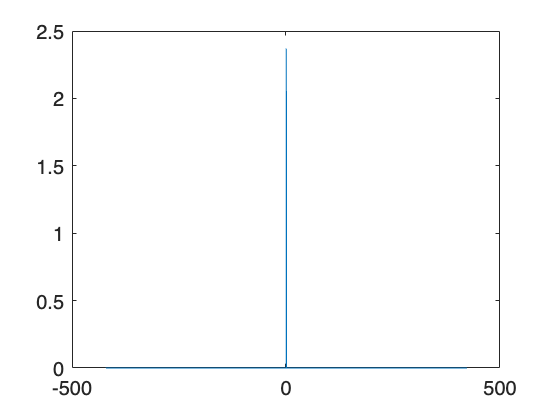

plot(t2, deltaD(t2-t00,D))

Visualise the approximate impulse `deltaD(a*t,D)` for diﬀerent values of the scaling parameter `a`. 

a = rand

a = 0.7922

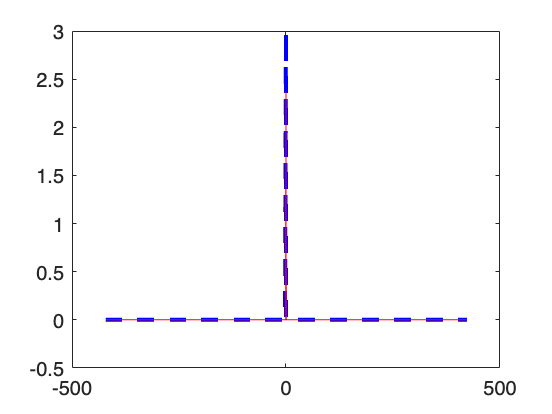

deltaA = deltaD(t2, D)/abs(a);
plot(t2, deltaA, "b--", "LineWidth",2); hold on
plot(t2, deltaD(a*t2, D), "r")

Explain why these results are consistent with the following known property of the ideal impulse.

...